# ENC analysis for each channel and ASIC

% clear; clc;

N = 300

N = 300

f_ENC =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


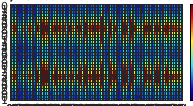

f_ENC =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


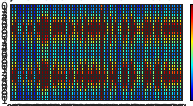

f_ENC =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


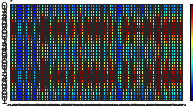

f_ENC =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


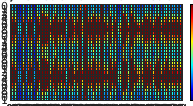

f_ENC =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


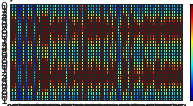

f_ENC =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


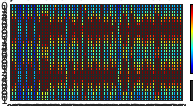

f_ENC =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


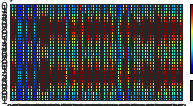

f_ENC =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0.0026 0.0046 0.8948 0.8722]
       Units: 'normalized'

  Show all properties


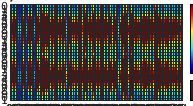


main_folder = 'aggregated_ENC/';
if (~exist(main_folder,'dir'))
    mkdir(main_folder);
end

enc = nan(32,N);
class_A_idxs = nan(8,N);
class_B_idxs = nan(8,N);

for j=0:7
    for i=0:N-1
        number = sprintf('%03i',i);
        if (exist(['FEB_Test/MODULE_',number,'/1/analysis_matlab/ENC/normal/ENC_normal.dat']))
            data = importdata(['FEB_Test/MODULE_',number,'/1/analysis_matlab/ENC/normal/ENC_normal.dat']);
            enc(:,i+1) = data.data(j+1:8:end,6);
        end
    end

    enc(isnan(enc) | enc <= 0) = nan;

    % remove invalid FEBs
    plot_enc = enc(:,~isnan(enc(1,:)));
    asic_n = 0:1:N-1;
    plot_asic_n = asic_n(~isnan(enc(1,:)));

    f_ENC = figure('units','normalized','outerposition',[0 0 .9 .9])
    subaxis(1,1,1,'Padding', 0.04, 'Margin', 0.01);
    heatmap(plot_enc,'XDisplayLabels',plot_asic_n,'YDisplayLabels',0:1:31);
    colormap('jet');
    xlabel('#FEB');
    ylabel('#Channel');
    caxis([0,20])

    title(sprintf('ENC (cubic gain, no outliers) for each channel in each FEB [keV]. Peaking time #%i',j));
    saveas(gcf,sprintf([main_folder, 'ENC_tau%i.svg'],j));
    savefig(sprintf([main_folder, 'ENC_tau%i.fig'],j));
    
    file_out = sprintf([main_folder, 'ENC_tau%i.dat'],j);
    
    fileID = fopen(file_out,'w');
    fprintf(fileID,'#---------------------------------------------------------\n');
    fprintf(fileID,'# ENC (cubic gain, no outliers) for each channel in each FEB [keV]. Peaking time = %i\n',j);
    fprintf(fileID,'# Rows: #Channels\n');
    fprintf(fileID,'# Columns: #FEB\n');
    fprintf(fileID,'#---------------------------------------------------------\n');
    s = repmat('%2.3f\t',1,N);
    s(end+1:end+2) = '\n';
    fprintf(fileID,s,enc');
    fclose(fileID);
    
    temp = isnan(enc) | enc >= 20;
    temp = sum(temp);
    temp_A = temp == 0;
    temp_B = temp >= 1 & temp <= 5;
    class_A_idxs(j+1,:) = temp_A;
    class_B_idxs(j+1,:) = temp_B;
end

## ASIC Classification

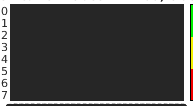

classification = nan(8,N);
classification(class_A_idxs == 1) = 3;
classification(class_B_idxs == 1) = 2;
classification(isnan(classification)) = 1;

figure('units','normalized','outerposition',[0 0 1 1])
subaxis(1,1,1,'Padding', 0.04, 'Margin', 0.01);
heatmap(classification,'XDisplayLabels',0:1:N-1,'YDisplayLabels',0:1:7);
xlabel('#FEB');
ylabel('#Channel');
title('FEB Classification. Class A = 100, Class B = 10');
colormap([0.95,0,0; ...
          0.95,0.95,0; ...
          0,0.95,0])
saveas(gcf,sprintf([main_folder, 'Classification.svg']));



temp = sum(class_A_idxs,1);
ASIC_class_A = temp == 8;
temp = class_A_idxs | class_B_idxs;
temp = sum(temp,1);
ASIC_class_B = temp == 8;
ASIC_class_B(ASIC_class_A) = 0;

tempA = find(ASIC_class_A == 1) - 1;
tempB = find(ASIC_class_B == 1) - 1;
display(['Class A FEBs: ', sprintf(repmat('%i\t',1,length(tempA)), tempA)])

Class A FEBs: 2	4	9	10	11	16	17	21	23	24	44	104	128	213	282	


display(['Class B FEBs: ', sprintf(repmat('%i\t',1,length(tempB)), tempB)])

Class B FEBs: 26	158	161	206	207	214	222	247	



file_out = [main_folder, 'FEB_Classification_A.dat'];

fileID = fopen(file_out,'w');
fprintf(fileID,'#---------------------------------------------------------\n');
fprintf(fileID,'# A-class FEBs.\n');
fprintf(fileID,'# Columns: #FEB\n');
fprintf(fileID,'#---------------------------------------------------------\n');
s = repmat('%i\t',1,length(tempA));
fprintf(fileID,s,tempA);
fclose(fileID);

file_out = [main_folder, 'FEB_Classification_B.dat'];

fileID = fopen(file_out,'w');
fprintf(fileID,'#---------------------------------------------------------\n');
fprintf(fileID,'# B-class FEBs.\n');
fprintf(fileID,'# Columns: #FEB\n');
fprintf(fileID,'#---------------------------------------------------------\n');
s = repmat('%i\t',1,length(tempB));
fprintf(fileID,s,tempB);
fclose(fileID);